
$$\bar  P(\theta) = \bar C + cos(\theta) \cdot \bar U + sin(\theta) \cdot \bar V$$


Where:


$$0.0      \space
\le       \space 
\theta  \space 
\le       \space 
2 \cdot \pi
$$



$$\bar U \space 
\circ\space
\bar V \space
= \space 0
$$



$$\big \vert \bar U \big \vert \space = \space semimajor \space axis$$



$$\big \vert \bar V \big \vert \space = \space semiminor \space axis$$



$$\bar C = (
Cx, \space  
Cy, \space 
Cz
) $$



$$\bar V = (
Vx, \space  
Vy, \space 
Vz
) $$



$$\bar U = (
Ux, \space  
Uy, \space 
Uz
) $$


3d Ellipse


$$cos(\theta) \cdot [U_x \space U_y \space U_z]

\space + \space

sin(\theta) \cdot [V_x \space V_y \space V_z]

\space + \space

[C_x \space C_y \space C_z]

=

[P_x \space P_y \space P_z]$$



$$
=
\bar P(\theta) 

$$


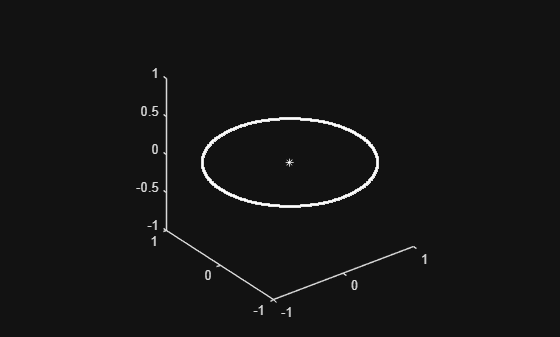

figure(1)
plot3(0,0,0,'w*');
axis equal;
hold on;
sind_0_000_ = 0.0;
for theta = 0:360
  P = cosd(theta) .* [1 0 0] + ...
      sind(theta) .* [0 1 0] + ...
      sind_0_000_ .* [0 0 1];
  plot3(P(1), P(2), P(3),'w.')
end
hold off;

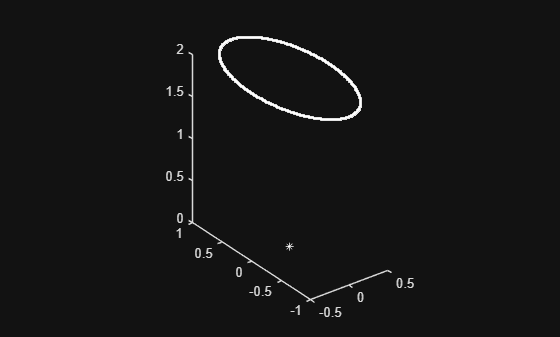

figure(2)
plot3(0,0,0,'w*');
axis equal;
hold on;
cosd_0_000_ = 1.0;
for theta = 0:360
  P = 0.5 .* cosd(theta) .* [1 0 0] + ...
      1.0 .* sind(theta) .* [0 1 0] + ...
      2.0 .* cosd_0_000_ .* [0 0 1];
  plot3(P(1), P(2), P(3),'w.')
end
hold off;


$$\frac{x^2}{a^2}

+ 

\frac{y^2}{b^2}

+ 

\frac{z^2}{c^2}

=

1$$



$$x = a \cdot sin(\theta) \cdot cos(\phi)$$



$$y = b \cdot sin(\theta) \cdot sin(\phi)$$



$$z = c \cdot cos(\theta)$$


Where:


$$0 \le \theta \le \pi$$



$$0 \le \phi \le 2 \cdot \pi$$


Volume


$$\frac{4}{3} \cdot \pi \cdot a \cdot b \cdot c$$



$$\frac{4}{3} \cdot \pi \cdot r \cdot r \cdot r = \frac{4}{3} \cdot \pi \cdot r^3$$


Surface area of ellipse:


$$Area = \pi \cdot a \cdot b$$


Perimeter of ellipse is integral

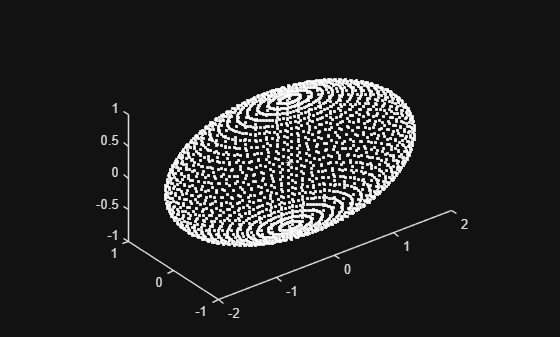

figure(3)
plot3(0,0,0,'w*');
axis equal;
hold on;

for theta = 0:5:180
  for phi = 0:5:360
    P = 2.0 .* sind(theta).*cosd(phi) .* [1 0 0] + ...
        1.0 .* sind(theta).*sind(phi) .* [0 1 0] + ...
        1.0 .* cosd(theta)            .* [0 0 1];
    plot3(P(1), P(2), P(3),'w.');
  end
end

% the = (0:5:180).';
% phi = (0:10:360).';
% P = 2.0 .* sind(the).*cosd(phi) * [1 0 0] + ...
%     1.0 .* sind(the).*sind(phi) * [0 1 0] + ...
%     1.0 .* cosd(the)            * [0 0 1];
% plot3(P(:, 1), P(:,2), P(:,3),'w.');

hold off;


$$x = x_0 + a \cdot t

$$



$$y = y_0 + b \cdot t$$



$$z = z_0 + c \cdot t$$


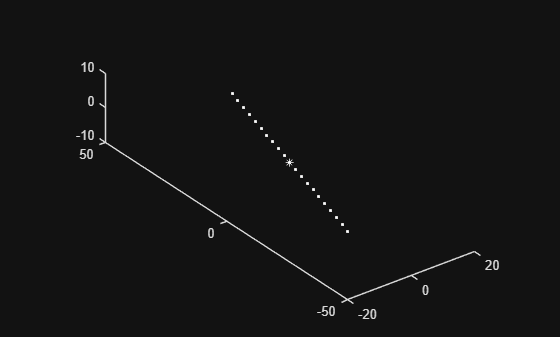

figure(4)
plot3(0,0,0,'w*');
axis equal;
hold on;
a = 2;
b = 5;
c = -1;
for t = -10:1:+10
  % P = [1 1 1] + [a*t b*t c*t];
  P = a*t .* [1 0 0] + ...
      b*t .* [0 1 0] + ...
      c*t .* [0 0 1];
  plot3(P(1), P(2), P(3),'w.');
end
hold off;